# Actividad 1 (Velocidades Lineales y angulares)

Oscar Ortiz Torres A01769292

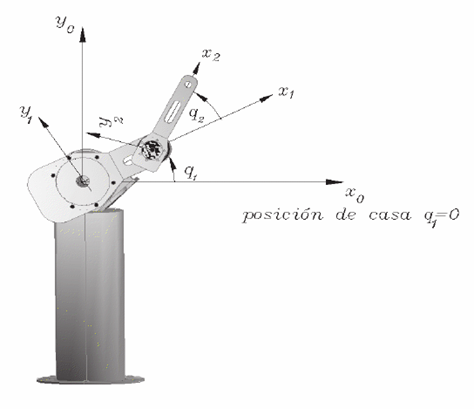

% Limpieza de pantalla
clear all
close all
clc

% Declaración de variables simbólicas
syms th1(t) l1 t th2(t) l2

% Configuración del robot
RP = [0, 0];

% Creación del vector de coordenadas articulares
disp('Coordenandas articulares'); Q = [th1, th2]

Coordenandas articulares


$$Q(t) = \left(\begin{array}{cc} {\mathrm{th}}_{1}\left(t\right) & {\mathrm{th}}_{2}\left(t\right) \end{array}\right)$$

% Creación del vector de velocidades articulares
disp('Velocidades articulares'); Qp = diff(Q,t) % Uso de diff para derivadas cuya variable de referencia no depende de otra

Velocidades articulares


$$Qp(t) = \left(\begin{array}{cc} \frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right) & \frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right) \end{array}\right)$$

% Número de grado de libertad del robot
GDL = size(RP, 2)

GDL = 2

## Articulación 1

% Posición de la junta 1 respecto a la 0
P(:,:,1) = [
            l1*cos(th1);
            l1*sin(th1);
            0
           ];

% Matriz de rotación de la articulación 1 respecto a la 0
R(:,:,1) = [
            cos(th1)    -sin(th1)   0;
            sin(th1)     cos(th1)   0;
            0            0          1
           ];


## Articulación 2

% Posición de la junta 2 respecto a la 1
P(:,:,2) = [
            l2*cos(th2);
            l2*sin(th2);
            0
           ];

% Matriz de rotación de la articulación 2 respecto a la 1
R(:,:,2) = [
            cos(th2)    -sin(th2)   0;
            sin(th2)     cos(th2)   0;
            0            0          1
           ];

## Matrices de transformación

% Creación del vector de ceros
vector_zeros = zeros(1,3);

% Inicialización de las matrices de Transformación Homogenea locales
A(:, :, GDL) = simplify([ ...
                        R(:,:,GDL)      P(:,:,GDL); ...
                        vector_zeros    1 ...
                        ]);

% Inicialización de las matrices de Tranformación Homogenea globales
T(:,:,GDL) = simplify([ ...
                        R(:,:,GDL)      P(:,:,GDL); ...
                        vector_zeros    1 ...
                        ]);


% Inicialización de los vectores de posición vistos desde el marco de referencia inercial
PO(:,:,GDL) = P(:,:,GDL);

% Inicialización de las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL) = R(:,:,GDL);

for i = 1:GDL
    i_str = num2str(i);

    % Locales
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i) = simplify([ ...
                         R(:,:,i)       P(:,:,i); ...
                         vector_zeros   1 ...
                        ]);
    A(:,:,i)

    % Globales
    try
        T(:,:,i) = T(:,:,i-1)*A(:,:,i);
    catch
        T(:,:,i) = A(:,:,i); % Caso específico cuando i=1 nos marcaría error en try
    end

    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i) = simplify(T(:,:,i));
    T(:,:,i)

    % Obtención de la matriz de rotación "RO" y el vector de traslación PO
    % de la matriz de transformación homogenea global T(:,:, GDL)
    RO(:,:,i) = T(1:3,1:3,i);
    PO(:,:,i) = T(1:3,4,i);
    disp(strcat('Matriz de Rotación RO', i_str)); RO(:,:,i)
    disp(strcat('Vector de Traslación PO', i_str)); PO(:,:,i)
end

Matriz de Transformación local A1


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación global T1


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Rotación RO1


$$ans = \left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Vector de Traslación PO1


$$ans = \left(\begin{array}{c} l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

Matriz de Transformación local A2


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & 0 & l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación global T2


$$ans = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sigma_{2}\\ \sigma_{1} & \sigma_{2} & 0 & l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sigma_{1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{2}=\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) \end{array}$$

Matriz de Rotación RO2


$$ans = \left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & 0\\ \sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Vector de Traslación PO2


$$ans = \left(\begin{array}{c} l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ 0 \end{array}\right)$$

## Calculo del Jacobiano lineal de forma diferencial

% Calculo de matriz homogenea global del sistema
MG = A(:,:,1) * A(:,:,2);  

% Definición de variables en base a la matriz homogenea resultante
x1 = MG(1,4);
y1 = MG(2,4);
z1 = MG(3,4);

% Derivada pacial de x respecto a th1
Jv11 = functionalDerivative(x1, th1);
% Derivada pacial de x respecto a th2
Jv12 = functionalDerivative(x1, th2);

% Derivada pacial de y respecto a th1
Jv21 = functionalDerivative(y1, th1);
% Derivada pacial de y respecto a th2
Jv22 = functionalDerivative(y1, th2);

% Derivada pacial de z respecto a th1
Jv31 = functionalDerivative(z1, th1);
% Derivada pacial de z respecto a th2
Jv32 = functionalDerivative(z1, th2);

% Cinemática diferencial del péndulo a partir de la cinemática directa
jv_d = simplify([ ...
                Jv11, Jv12; ...
                Jv21, Jv22; ...
                Jv31, Jv32 ...
                ]);
disp('Jacobiano linel obtenido de forma diferencial'); jv_d

Jacobiano linel obtenido de forma diferencial


$$jv\_d(t) = \left(\begin{array}{cc} -l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)-l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & -l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 \end{array}\right)$$

## Calculo del jacobiano lineal y angular de forma analítica

% Inicialización de jacobianos analíticos (lineal y angular)
Jv_a(:,GDL) = PO(:,:,GDL);
Jw_a(:,GDL) = PO(:,:,GDL);

for k = 1:GDL
    %if((RP(k) == 0) | (RP(k) == 1)) % Casos: articulación rotacional y prismática
    if(RP(k) == 0)
        % Para las articulaciones rotacionales
        try
            Jv_a(:,k) = cross(RO(:,3,k-1), PO(:,:,GDL) - PO(:,:,k-1));
            Jw_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = cross([0 0 1], PO(:,:,GDL)); % Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k) = [0 0 1]; % Si no hay matriz de rotación previa se obtiene la matriz identidad
        end
    elseif(RP(k) == 1)
        % Para las articulaciones prismáticas
        try
            Jv_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = [0,0,1]; % Si no hay matriz de rotación previa se obtiene la matriz identidad
        end
            Jw_a(:,k) = [0 0 0];
    end
end

## Despliegue

disp('Jacobiano lineal obtenido de forma analítica'); Jv_a = simplify(Jv_a) %pretty(Jv_a)

Jacobiano lineal obtenido de forma analítica


$$Jv\_a = \left(\begin{array}{cc} -l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)-l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & -l_{2}\,\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) & l_{2}\,\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 \end{array}\right)$$

disp('Jacobiano angular obtenido de forma ananlítica'); Jw_a = simplify(Jw_a) %pretty(Jw_a)

Jacobiano angular obtenido de forma ananlítica


$$Jw\_a = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 1 \end{array}\right)$$

disp('Velocidad lineal obtenida mediante el Jacobiano lineal'); V = simplify(Jv_a * Qp') %pretty(V);

Velocidad lineal obtenida mediante el Jacobiano lineal


$$V(t) = \begin{array}{l} \left(\begin{array}{c} -\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}\,\left(l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sigma_{1}\right)-l_{2}\,\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}\,\sigma_{1}\\ \bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}\,\left(l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sigma_{2}\right)+l_{2}\,\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}\,\sigma_{2}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{2}=\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) \end{array}$$

disp('Velocidad angular obtenida mediante el Jacobiano angular'); W = simplify(Jw_a * Qp') %pretty(W);

Velocidad angular obtenida mediante el Jacobiano angular


$$W(t) = \left(\begin{array}{c} 0\\ 0\\ \bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}+\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)} \end{array}\right)$$